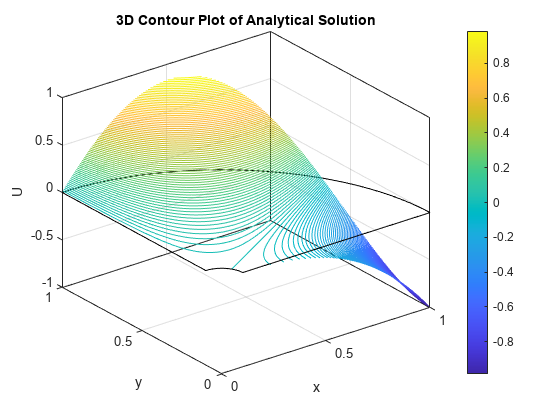

%%%% HW 1

% Parameters
a = 0.1;
R = 1;
th_final = pi/2;
b = a^6;

N = 100;

% Function for U(r, th)
U = @(r, th) - (r.^3 + b*r.^(-3)) / (1 + b) .* cos(3*th);

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);

r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);

x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);

U_mesh = U(r_mesh, th_mesh);

figure
contour3(x_coor, y_coor, U_mesh, 151)
hold on
plot3(zeros(N, 1), linspace(a, R, N), zeros(N, 1), 'k')
plot3(linspace(a, R, N), zeros(N, 1), zeros(N, 1), 'k')
plot3(a*cos(th_range), a*sin(th_range), zeros(N, 1), 'k')
plot3(R*cos(th_range), R*sin(th_range), zeros(N, 1), 'k')
title('3D Contour Plot of Analytical Solution')
xlabel('x')
ylabel('y')
zlabel('U')
colorbar
exportgraphics(gcf, 'ContourPlot.png', 'Resolution',300)

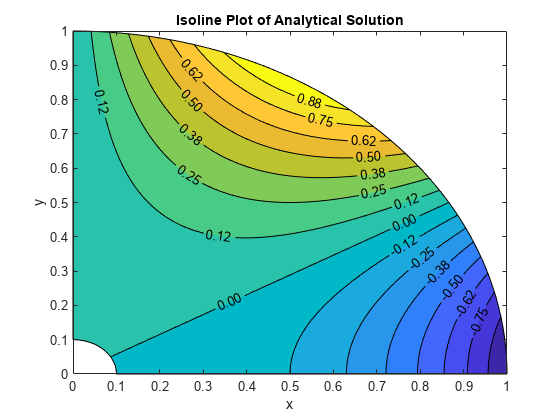


figure
contourf(x_coor, y_coor, U_mesh, 15, "ShowText","on", "LabelFormat","%0.2f")
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Isoline Plot of Analytical Solution')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)